# Создаём и обрабатываем аккорд в MATLAB

## Создание синусоиды 440 Гц - ноты Ля

Для отрисовки графика тостой линией в команду ***plot*** добавляется аргумент ***LineWidth*** значением 2. Функция ***xlim*** позволяет настроить пределы отрисовки графика по оси х. Команда ***grid on*** добавляет на график сетку. Команда ***sound*** проигрывает аудио, помимо сигнала ей также важно передать частоту дискретизации.

fc = 440;
fs = 8000;
dt = 1/fs;
t = 0:dt:0.1;
L=length(t)

L = 801

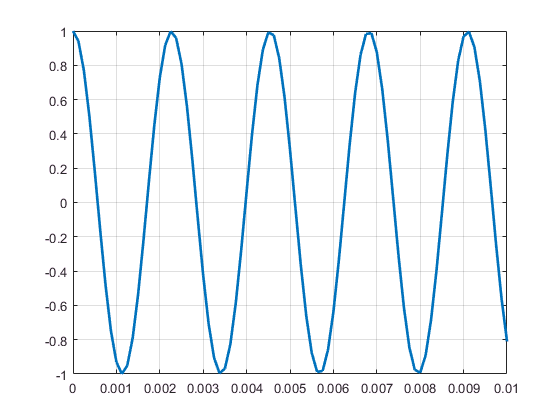

x = cos(2*pi*fc*t);
plot(t,x,'LineWidth',2); xlim([0 0.01]); grid on;

sound(x,fs); pause(1.5);

## Создание трёх синусоид - нот Ля, До диез и Ми

Вектор частот ***fc*** - это столбец, в то время как вектор времени ***t*** - строка. Перемножение столбца на строку даёт в результате матрицу ***y*** из трёх строк. Команда ***pause(0.5)*** задаёт паузу в 0.5 сек между командами ***sound***.

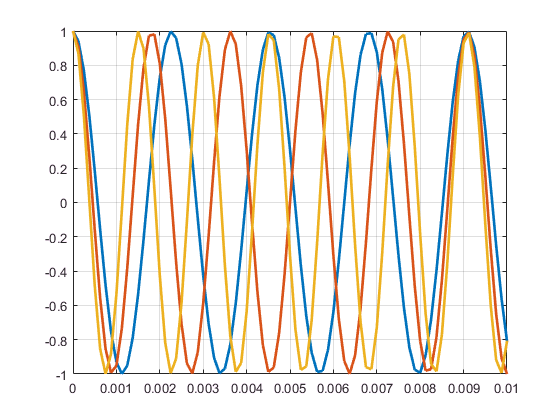

fc = [440; 550; 660];
y = cos(2*pi*fc*t);
plot(t,y,'LineWidth',2); xlim([0 0.01]); grid on;

sound(y(1,:),fs); pause(0.95);
sound(y(2,:),fs); pause(0.95);
sound(y(3,:),fs)

## Создание суммы синусоид - аккорда Ля мажор

Статистическая функция ***sum*** складывает элементы в столбцах матрицы. Результирующая строка - сумма трёх синусоид, которая затем нормируется таким образом, чтобы сигнал лежал в пределах [-1 1]. Функция ***repmat*** позволяет нам сделать копии строки ***z***, в даном случае мы делаем 10 копий по горизонтали. Результирующая строка ***Achord*** длиннее вектора ***z*** в 10 раз.

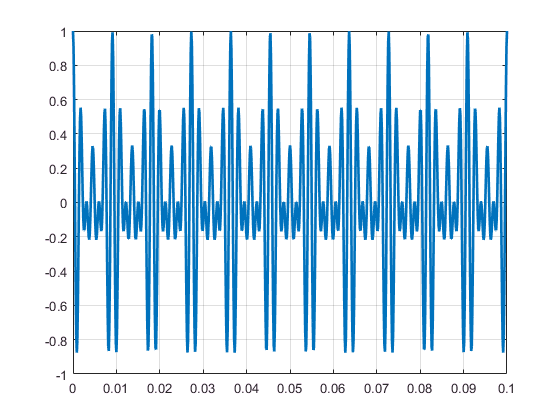

z = sum(y);
z = z/3;
plot(t,z,'LineWidth',2); xlim([0 0.1]); grid on;

Achord = repmat(z,1,10);
sound(Achord,fs)

## Обработка в Signal Analyzer - выделение тона До диез

После открытия окна ***Signal Analyzer*** мы загружаем сигнал ***Achord*** для отображения во временной и частотной областях, указываем частоту дискретизации, делаем копию сигнала, выделяем полосно-пропускающим фильтром (band pass) частоты от 540 до 560 Гц, тем самым выбрав из смеси тон До диез, и сохраняем результат в рабочее пространство под именем переменной ***Csharp***. Для того, чтобы мы могли отразить её на графике с вектором ***t***, необходимо взять первые 801 отсчёт сигнала, так как длины векоторов, передаваемых команде ***plot,*** должны совпадать.

% signalAnalyzer
% plot(t,Csharp(1:801),'LineWidth',2); xlim([0 0.01]); grid on;
% sound(Csharp,fs)
Z=fft(z); % преобразование Фурье от аккорда
P2 = abs(Z/L);
P1 = P2(1:L/2+1);

P1(2:end-1) = 2*P1(2:end-1);

Найдем величину частотного диапазона `f` и построим односторонний амплитудно- частотный спектр  сигнала `P1`.

L=length(t)

L = 801

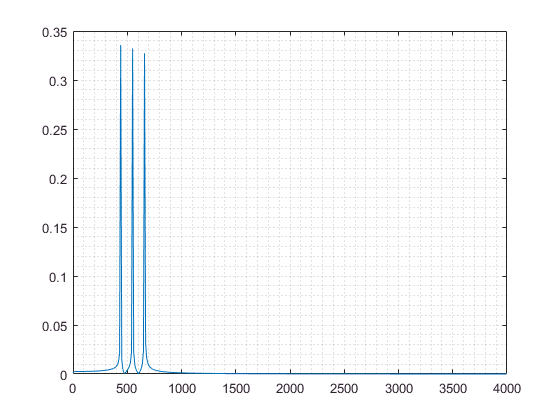

f = fs*(0:(L/2))/L;
figure,plot(f,P1);
grid minor